# ------------------ UVSPEC WRAPPER -----------------

% -----------------------------------------------------------


% This script will write .INP files using writeUVSPEC.m, run the created
% files using runUVSPEC/m, and then read the .OUT files using readUVSPEC.m.
% The intention of the script is to control the radiative transfer code
% UVSPEC from Matlab. The user will be able to create files, run them and
% view the results here in this live script


clear variables; close all;


% Created by Andrew J. Buggee

## DESIGNATE FOLDER, INPUT AND OUTPUT FILES

% for now, we will manually create uvspec.inp files, and simply call them
% out as variables

% folderName = ['/Users/andrewbuggee/Documents/CU-Boulder-ATOC/',...
%     'Hyperspectral-Cloud-Droplet-Retrieval-Research/LibRadTran/',...
%     'libRadtran-2.0.4/examples/'];


folderName = ['/Users/andrewbuggee/Documents/CU-Boulder-ATOC/Hyperspectral-Cloud-Droplet-Retrieval-Research/',...
    'LibRadTran/libRadtran-2.0.4/Reflectance_Function/'];

% inputName = 'UVSPEC_RADIANCES.INP';
% inputName = 'UVSPEC_CLEAR_2.INP';
% inputName = 'UVSPEC_REPTRAN_SOLAR.INP';
% inputName = 'UVSPEC_REPTRAN_SOLAR_2.INP';
% inputName = 'TEST_EXAMPLE_1.INP';
% inputName = 'UVSPEC_REPTRAN_THERMAL.INP';
% inputName = {'TEST_EXAMPLE_0.INP','TEST_EXAMPLE_45.INP','TEST_EXAMPLE_75.INP'};
% inputName = 'UVSPEC_CLOUDCOVER_4.INP'; % run from 500-4000 nm
inputName = {'065_micronBand_droplets_2_5_microns.INP','065_micronBand_droplets_4_microns.INP',...
    '065_micronBand_droplets_6_microns.INP','065_micronBand_droplets_10_microns.INP',...
    '065_micronBand_droplets_20_microns.INP'};

outputName = {'output_065_micronBand_droplets_2_5_micron','output_065_micronBand_droplets_4_micron',...
    'output_065_micronBand_droplets_6_micron','output_065_micronBand_droplets_10_micron',...
    'output_065_micronBand_droplets_20_micron'};
% outputName = {'outputTest0.OUT','outputTest45.OUT','outputTest75.OUT'};



## RUN UVSPEC AND SAVE INPUTS/OUTPUTS

[inputSettings] = runUVSPEC(folderName,inputName,outputName);

if length(outputName)>1

    save([folderName,'GROUP_',outputName{1},'_settings.mat'],"inputSettings"); % save inputSettings to the same folder as the input and output file

else
    save([folderName,outputName,'_settings.mat'],"inputSettings"); % save inputSettings to the same folder as the input and output file
end




## READ UVSPEC OUTPUT FILES

if length(outputName)==1

    [ds,irrad_HU,rad_HU] = readUVSPEC(folderName,outputName,inputSettings);

elseif length(outputName)>1

    ds = cell(1,length(outputName));

    for jj = 1:length(outputName)

        [ds{jj},irrad_HU,rad_HU] = readUVSPEC(folderName,outputName{jj},inputSettings); % headers don't change per iteration

    end
end





## PLOT AND ANALYZE OUTPUT FILES

% If using the live script, always run these plot properties
liveScriptPlotting

% First lets plot the Irradiance Data

figure;
p1 = plot(ds.wavelength,ds.irradiance.totDwnIrrad,'LineWidth',1);
grid on; grid minor
title(irrad_HU{1,8})
xlabel(irrad_HU{2,1})
ylabel(irrad_HU{2,2})
%p1.Parent.Position(3) = 1; % this will make the subplots wider by 300 pixels
% xlim([min(ds.wavelength) max(ds.wavelength)])


% Next lets plot the radiance data

% lets check and see how many geometry settings there are

geomSets = length(inputSettings{2})*length(inputSettings{3});

if geomSets <= 3

    figure;
    legendString = cell(1,geomSets);
    for ii = 1:geomSets
        plot(ds.wavelength,ds.radiance(ii).rad_umu_phi,'LineWidth',1)
        hold on
        legendString{ii} = ds.radiance(ii).umu_phi;
    end

    grid on; grid minor
    title(rad_HU{1,2})
    xlabel(irrad_HU{2,1})
    ylabel(rad_HU{2,2})
    legend(legendString,'TextColor','w')

elseif geomSets > 3

    index2plot = [1,3,5];


    figure;
    sp1 = subplot(1,2,1);
    legendString = cell(1,length(index2plot));
    for ii = 1:length(index2plot)
        plot(ds.wavelength,ds.radiance(index2plot(ii)).rad_umu_phi,'LineWidth',1)
        hold on
        legendString{ii} = ds.radiance(index2plot(ii)+1).geometry;
    end

    sp1.Parent.Position(3) = sp1.Parent.Position(3)+300; % this will make the subplots wider by 300 pixels
    grid on; grid minor
    title(rad_HU{1,2})
    xlabel(irrad_HU{2,1})
    ylabel(rad_HU{2,2})
    legend(legendString,'TextColor','w')

    r = 1;
    sp2 = subplot(1,2,2);
    % Plot the position of the sun
    polarplot(pi/180*inputSettings{5},r*sind(inputSettings{4}),'*','MarkerSize',15,'Color',[0.9290, 0.6940, 0.1250])
    hold on
    set(gca,'ColorOrderIndex',1)
    for ii = 1:length(index2plot)
        geom = str2num(ds.radiance(index2plot(ii)+1).geometry); %#ok<ST2NM> % first value is umu, second is azimuth
        sinT = sqrt(1 - geom(1).^2);

        polarplot(pi/180*geom(2),r*sinT,'.','MarkerSize',12)
        hold on
    end
    set(gca,'FontSize',14)
    title('Geometry of Sun and Looks','FontSize',20)



end

## CALCULATE REFLECTANCE FUNCTION

if length(outputName)==1
    [R,Rl] = reflectanceFunction(inputSettings,ds);

elseif length(outputName)>1
    R = cell(1,length(outputName));
    Rl = cell(1,length(outputName));

    for jj = 1:length(outputName)

        [R{jj},Rl{jj}] = reflectanceFunction(inputSettings(:,jj),ds{jj});
    end
end


## PLOT REFLECTANCE FUNCTION

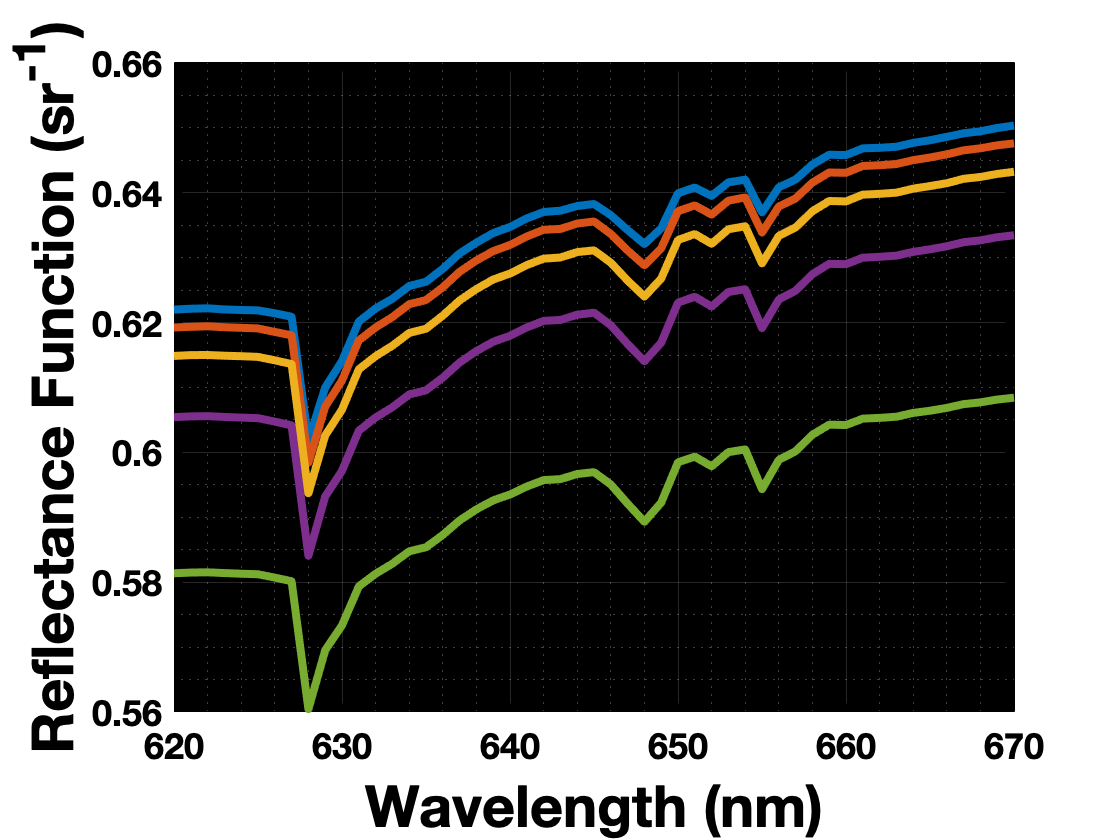

liveScriptPlotting;

if length(outputName)==1

    figure; plot(ds.wavelength,Rl)
    xlabel('Wavelength (nm)')
    ylabel('Reflectance Function (sr^{-1})')
    grid on; grid minor

elseif length(outputName)>1

    figure;

    for jj = 1:length(outputName)

        plot(ds{jj}.wavelength,Rl{jj})
        hold on;
    end
    xlabel('Wavelength (nm)')
    ylabel('Reflectance Function (sr^{-1})')
    grid on; grid minor

end